ECE40051  -  Signals &  Systems

Matlab Project  #1

  Name: Joel Arzapalo Guerra

1.Consider the following Matlab code, which generates a dsicrete-time sinusoidal signal x[n] and plot it:

(a)

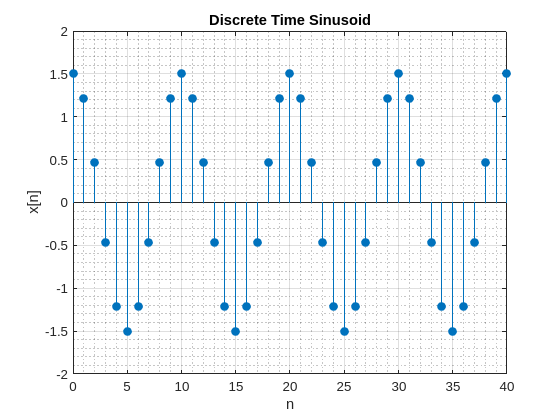

n = 0:40;                           % array n holds the values of the time variable.
omega = 0.1*2*pi;                   % frequency of the sinusoid.
phase_offset = 0;                   % phase offset.
A = 1.5;                            % amplitude.
arg = omega*n-phase_offset;         % note that "arg" is an array the same size as n.
xn = A*cos(arg);                    % values of the signal x[n].
stem(n, xn, "filled");
axis([0 40 -2 2]);
grid on; grid minor;
title("Discrete Time Sinusoid");
xlabel("n"); ylabel("x[n]");  

(b) The length L and the period N of the signal are:

L = 41;
N = 2*pi/omega; % N = 10.
disp(N);

    10



(c) The axis command is used to set the axis limits in the plot. In these case the x-axis is limit from 0 to 40 and the y-axis is limit from -2 to 2.

(d) The grid command is used to show or hide the grid in the plot, in these case to show the grid.

(e) The plot command shows a continuos plot joining the points with lines. In contrast with the discrete points showing with the stem command.

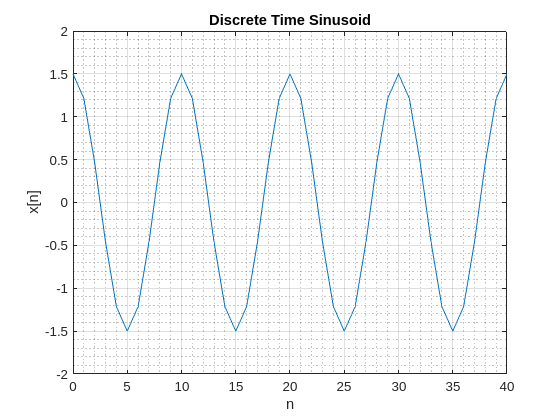

plot(n, xn);
axis([0 40 -2 2]);
grid on; grid minor;
title("Discrete Time Sinusoid");
xlabel("n"); ylabel("x[n]"); 

(f) Sinusoid modified with length 50, frequency 0.8π radians per sample, amplitude 2.5, and a phase offset of π/2 radians.

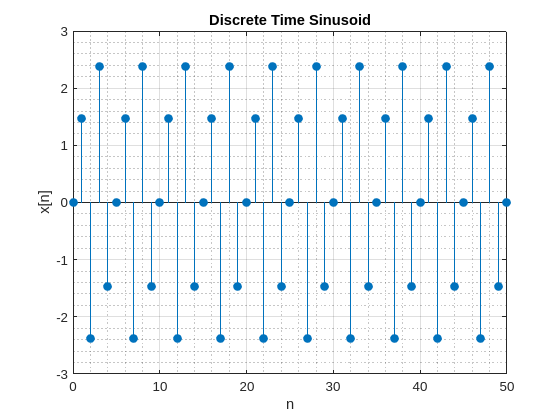

n = 0:50;                           % array n holds the values of the time variable.
omega = 0.4*2*pi;                   % frequency of the sinusoid.
phase_offset = pi/2;                % phase offset.
A = 2.5;                            % amplitude.
arg = omega*n-phase_offset;         % note that "arg" is an array the same size as n.
xn = A*cos(arg);                    % values of the signal x[n].
stem(n, xn, 'filled');
axis([0 50 -3 3]);
grid on; grid minor;
title("Discrete Time Sinusoid");
xlabel("n"); ylabel("x[n]");

2. With  x[n]= δ[n]+2δ[n − 1] − δ[n − 3] + 3δ[n − 4] − δ[n − 5] and h[n]=2δ[n]+2δ[n − 2] and using the modified code, it is seen in the plots that the output signal y2[n] is the output signal y1[n] shifted by 2. So the system is time invariant.

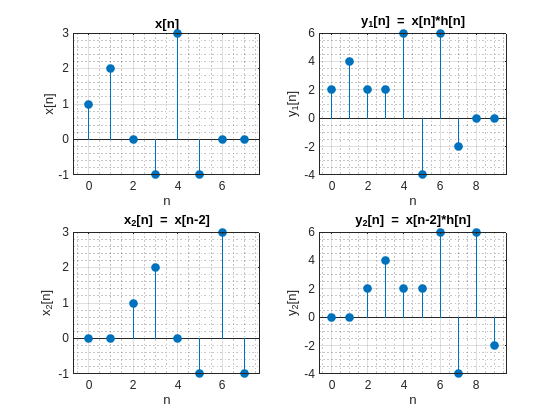

x = [1 2 0 -1 3 -1 0 0];   	    % Input signal zero-padded to length 8 
xm2 = [zeros(1,2) x(1:6)];   	% Shifted input signal x[n-2]
h = [2 0 2];  	 	            % Impulse response 
y1 = conv(x,h);   	 	        % y1[n] = x[n] * h[n] 
y2 = conv(xm2,h);  	 	        % y2[n] = x[n-2] * h[n]

n = 0:9;
n2 = 0:7;

figure;
subplot(2,2,1);
stem(n2, x, "filled");
title("x[n]");
xlabel("n");
ylabel("x[n]");
grid on; grid minor;

subplot(2,2,2);
stem(n, y1, "filled");
title("y_1[n] = x[n]*h[n]");
xlabel("n");
ylabel("y_1[n]");
grid on; grid minor;

subplot(2,2,3);
stem(n2, xm2, "filled");
title("x_2[n] = x[n-2]");
xlabel("n");
ylabel("x_2[n]");
grid on; grid minor;

subplot(2,2,4);
stem(n, y2, "filled");
title("y_2[n] = x[n-2]*h[n]");
xlabel("n");
ylabel("y_2[n]");
grid on; grid minor;

3. In the next plots it is seen that as the number of terms of the series increase the series converges to the continuos square wave.

(a) Graph of the first term of the series:

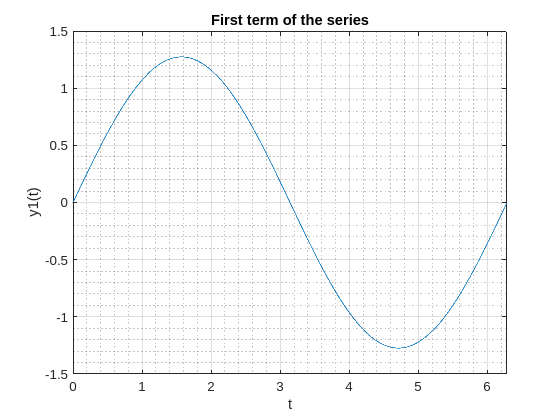

t = 0:2*pi/1000:2*pi;
y1 = 4/pi*sin(t);
figure;
plot(t, y1);
axis([0 2*pi -1.5 1.5]);
grid on; grid minor;
title("First term of the series");
xlabel("t"); ylabel("y1(t)");  

(b) Graph of the sum of the first two terms of the series:

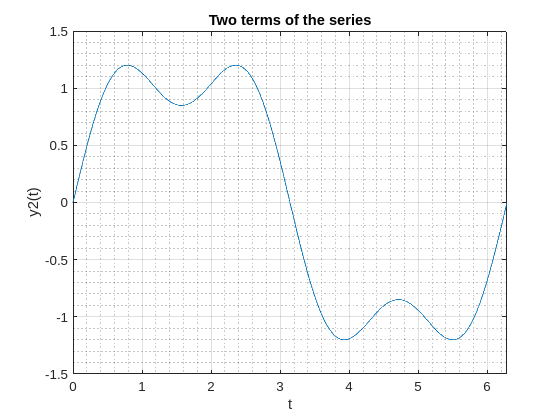

t = 0:2*pi/1000:2*pi;
y2 = 4/pi*sin(t) + 4/pi*sin(3*t)/3;
figure;
plot(t, y2);
axis([0 2*pi -1.5 1.5]);
grid on; grid minor;
title("Two terms of the series");
xlabel("t"); ylabel("y2(t)");

(c) Graph of the sum of the first eight terms of the series:

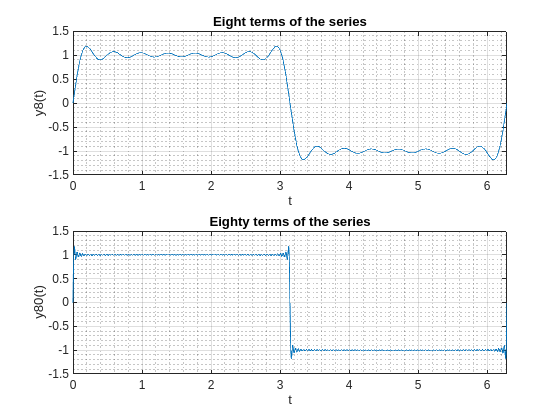

t = 0:2*pi/1000:2*pi;
y8 = zeros(1, length(t));
y80 = zeros(1, length(t));

N = 8;
for k=1:N
    y8 = y8 + 4/pi*sin((2*k-1)*t)/(2*k-1);
end

N = 80;
for k=1:N
    y80 = y80 + 4/pi*sin((2*k-1)*t)/(2*k-1);
end

figure;
subplot(2,1,1);
plot(t, y8);
axis([0 2*pi -1.5 1.5]);
grid on; grid minor;
title("Eight terms of the series");
xlabel("t"); ylabel("y8(t)");

subplot(2,1,2);
plot(t, y80);
axis([0 2*pi -1.5 1.5]);
grid on; grid minor;
title("Eighty terms of the series");
xlabel("t"); ylabel("y80(t)");

4. 

(a)

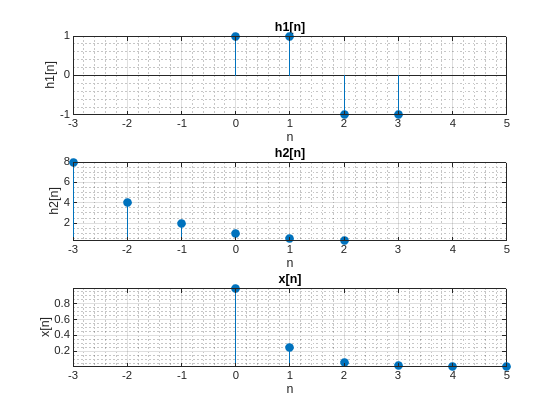

n1 = 0:3;
n2 = -3:2;
n3 = 0:5;
h1 = [1 1 -1 -1];   	        % Impulse response h1 
h2 = (1/2).^n2;   	        % Impulse response h2
x = (1/4).^n3;                % dicrete-time signal

figure;
subplot(3,1,1);
stem(n1, h1, "filled");
title("h1[n]");
xlabel("n");
ylabel("h1[n]");
grid on; grid minor;
axis([-3 5 -inf inf]);

subplot(3,1,2);
stem(n2, h2, "filled");
title("h2[n]");
xlabel("n");
ylabel("h2[n]");
grid on; grid minor;
axis([-3 5 -inf inf]);

subplot(3,1,3);
stem(n3, x, "filled");
title("x[n]");
xlabel("n");
ylabel("x[n]");
grid on; grid minor;
axis([-3 5 -inf inf]);

(b)

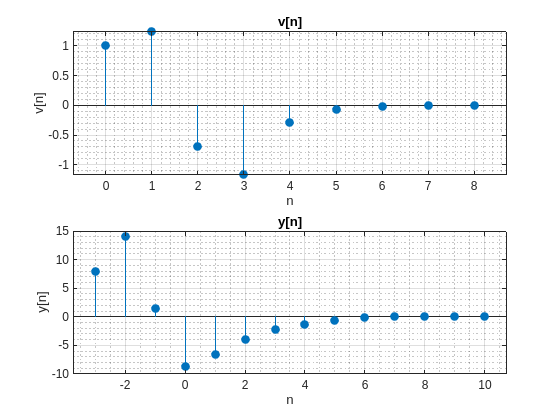

v = conv(x,h1);   	 	        % v[n] = x[n] * h1[n] 
y = conv(v,h2);  	 	        % y[n] = v[n] * h2[n]

n1 = 0:8;
n2 = -3:10;

figure;
subplot(2,1,1);
stem(n1, v, "filled");
title("v[n]");
xlabel("n");
ylabel("v[n]");
grid on; grid minor;

subplot(2,1,2);
stem(n2, y, "filled");
title("y[n]");
xlabel("n");
ylabel("y[n]");
grid on; grid minor;

(c) Because of the associative and conmitative properties of the convolution the final output y[n] but v[n] is diferent because it is the convolution of diferentes signals.

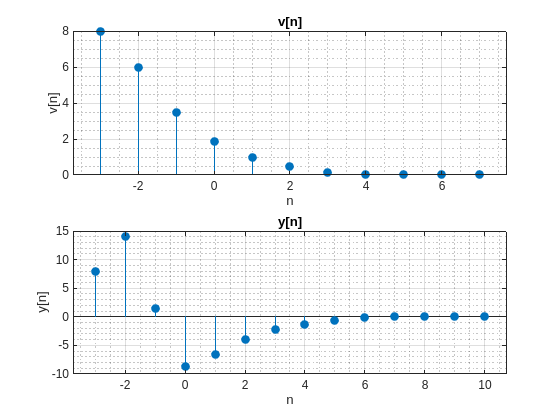

v = conv(x,h2);   	 	        % v[n] = x[n] * h1[n] 
y = conv(v,h1);  	 	        % y[n] = v[n] * h2[n]

n1 = -3:7;
n2 = -3:10;

figure;
subplot(2,1,1);
stem(n1, v, "filled");
title("v[n]");
xlabel("n");
ylabel("v[n]");
grid on; grid minor;

subplot(2,1,2);
stem(n2, y, "filled");
title("y[n]");
xlabel("n");
ylabel("y[n]");
grid on; grid minor;